## Minimizzazione del CV@R

clear all; close all; clc

Prima di tutto leggiamo i dati storici dei prezzi delle azioni di 4 aziende (Pfizer, Amazon, Apple, JPMorgan).

T = readtable('data.xlsx');
nasset = size(T,2)-1; % numero di aziende

Per calcolare i valori del CV@R al 90%, 95%, 99%, serve un numero sempre maggiore di scenari perché al crescere della percentuale ci spostiamo sempre di più verso la coda della distribuzione di probabilità.

Dal codice try_CVaR, ho ottenuto alcuni valori per far restare l'errore assoluto entro 0.010. Aprendo l'altro codice si vedono i ragionamenti fatti, qui riporto solo i risultati.

Per calcolcare il CV@R servono:

-  10 mila scenari al 90%;

- 16 mila scenari al 95%;

- 57 mila scenari al 99%.

alpha = 0.05;
if alpha == 0.1
    nScenario = 10000;
elseif alpha == 0.05
    nScenario = 16000;
elseif alpha == 0.01
    nScenario = 57000;
end

Il problema da risolvere è la minimizzazione del CV@R del portfaglio scelto, partendo da un budget iniziale e aspettandosi di fare un certo profitto.

problem = optimproblem("ObjectiveSense","min");
budgetiniziale = 1;    % unità di budget iniziale W0
budgetfinale = 1.0016; % budget minimo richiesto  WT
rng(0);
prezzistorici = table2array(T(:,2:end)); % prezzi giornalieri delle azioni delle aziende
dailyReturn = tick2ret(T{:,2:end});      % rendimenti giornalieri delle aziende
AssetScenarios = mvnrnd(mean(dailyReturn),cov(dailyReturn),nScenario); % scenari generati da una normale multivariata
                                                                       % basata sui dati storici
prezzifinali = ((1+AssetScenarios).*prezzistorici(end,:)); % prezzi delle azioni al giorno successivo per tutti i possibili scenrai
prezzoatteso = mean(prezzifinali,1); % valore medio del prezzo delle azioni delle aziende al giorno successivo

Definisco le variabili per il problema di ottimizzazione, i vincoli e la funzione obiettivo:

nstocks = optimvar('nstocks',nasset, 'LowerBound',0); %variabile che mi dice il numero di azioni da avere nel portafoglio Xi
z = optimvar('auxiliary',nScenario,'LowerBound',0); %variabile ausiliaria z 
VaR = optimvar('VaR',1,'LowerBound',0); %V@R zeta greca

problem.Constraints.budgetiniziale = prezzistorici(end,:)*nstocks == budgetiniziale; % vincolo iniziale del portafoglio
problem.Constraints.budgetfinale = prezzoatteso*nstocks >= budgetfinale; % vincolo finale del portafoglio
cons =  z >= budgetiniziale - prezzifinali*nstocks - VaR; 
problem.Constraints.auxiliary = cons;

problem.Objective = VaR + (1/(alpha*nScenario))*sum(z); % funzione obiettivo da minimizzare, il CV@R

La soluzione è:

[sol,CVaR] = solve(problem)

Solving problem using linprog.

Optimal solution found.



sol = struct with fields:
          VaR: 0.0273
    auxiliary: [16000×1 double]
      nstocks: [4×1 double]


CVaR = 0.0346

Posso confrontare il risultato ottenuto con il metodo che utilizza MATLAB per calcolare la frontiera efficiente del portafoglio:

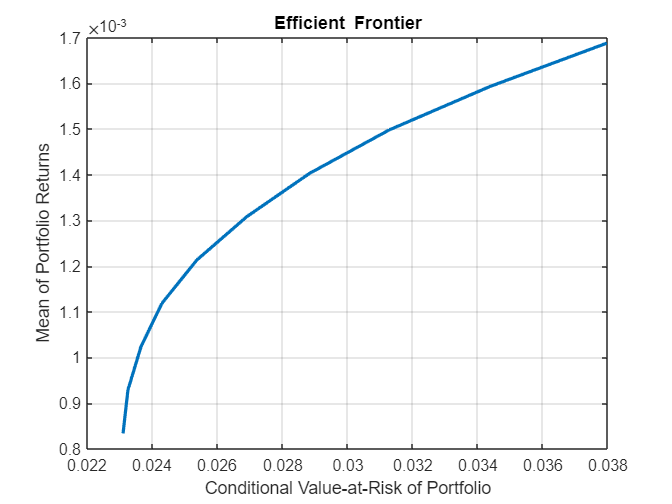

p1 = PortfolioCVaR('Scenarios', AssetScenarios); %
p1 = setDefaultConstraints(p1); 
p1 = setProbabilityLevel(p1, 1-alpha);
figure;
w1 = estimateFrontier(p1);
plotFrontier(p1,w1);

Ora ottenuti i valori di portafoglio ottimale posso calcolare il CV@R con dei campioni out of sample. Questi li simulo sempre da una normale multivarita ma prendendo come dati storici solo i rendimenti degli ultimi 10 giorni

CVaR_sim =zeros(1000,1);
for z=1:1000
    AssetScenarios_new = mvnrnd(mean(dailyReturn(end-9:end)),cov(dailyReturn(end-9:end)),nScenario); % nuovi campioni out of sample
    prezzifinali = ((1+AssetScenarios_new).*prezzistorici(end,:)); % prezzi delle azioni simulate
    profitto_finale = budgetiniziale-prezzifinali*sol.nstocks;     % valori simulati del profitto con il portafoglio ottimale
    CVaR_sim(z) = -sum(profitto_finale(profitto_finale<=-sol.VaR))/sum(profitto_finale<=-sol.VaR);
end
mean(CVaR_sim)

ans = 0.0359